clear;clc;close all

## Clustering Using Gaussian Mixture Models

## How Gaussian Mixture Models Cluster Data

Gaussian mixture models (GMM) are often used for data clustering. Usually, fitted GMMs cluster by assigning query data points to the multivariate normal components that maximize the component posterior probability given the data. That is, given a fitted GMM, [cluster](docid:stats_ug.brx2uny-1) assigns query data to the component yielding the highest posterior probability. This method of assigning a data point to exactly one cluster is called *hard* clustering. For an example showing how to fit a GMM to data, cluster using the fitted model, and estimate component posterior probabilities, see [Cluster Data from Mixture of Gaussian Distributions](docid:stats_ug.bra9fvn).

However, GMM clustering is more flexible because you can view it as a *fuzzy* or *soft clustering* method. Soft clustering methods assign a score to a data point for each cluster. The value of the score indicates the association strength of the data point to the cluster. As opposed to hard clustering methods, soft clustering methods are flexible in that they can assign a data point to more than one cluster. When clustering with GMMs, the score is the posterior probability. For an example of soft clustering using GMM, see [Cluster Gaussian Mixture Data Using Soft Clustering](docid:stats_ug.buqq83f).

Moreover, GMM clustering can accommodate clusters that have different sizes and correlation structures within them. Because of this, GMM clustering can be more appropriate to use than, e.g, *k*-means clustering.

Like most clustering methods, you must specify the number of desired clusters before fitting the model. The number of clusters specifies the number of components in the GMM. For GMMs, it is best practice to also consider the: 

- Component covariance structure. You can specify diagonal or full covariance matrices, or whether all components have the same covariance matrix.

- Initial conditions. The Expectation-Maximization (EM) algorithm fits the GMM. Like the *k*-means clustering algorithm, EM is sensitive to initial conditions and might converge to a local optimum. You can specify your own starting values for the parameters, specify initial cluster assignments for data points or let them be randomly chosen, or specify to use the *k*-means ++ algorithm.

- Regularization parameter. If, for example, you have more predictors than data points, then you can regularize for estimation stability.

## Covariance Structure Options

Load Fisher's iris data set. Consider clustering the sepal measurements.

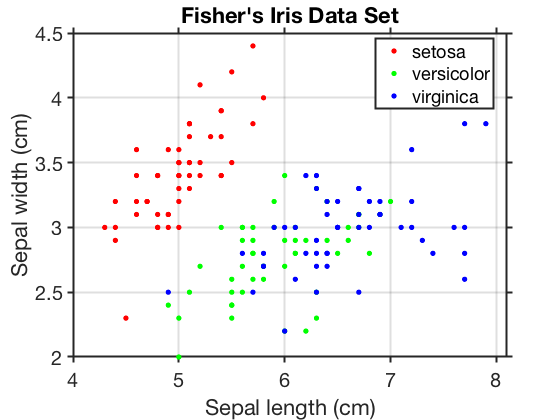

load fisheriris;
X = meas(:,1:2); 
[n,p] = size(X);
rng(3); % For reproducibility

figure;
gscatter(X(:,1),X(:,2),species);
title('Fisher''s Iris Data Set');
xlabel('Sepal length (cm)');ylabel('Sepal width (cm)');grid on
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','Fisher.eps');% save to an eps file

The number of components, *k*, in a GMM determines number of subpopulations or clusters. In this figure, it is difficult to determine whether two, three, or perhaps more components are appropriate. A GMM increases in complexity as *k* increases.

Each component has a covariance matrix. Geometrically, the covariance structure determines the shape of a confidence ellipsoid drawn over a subpopulation or cluster. You can specify whether the covariance matrices for all components are diagonal or full, or whether all components have the same covariance matrix. Each combination of specifications determines the shape and orientation of the ellipsoids.

Fit GMMs to the data and examine the effects of specifying all combinations of covariance structure options on the shape of the ellipsoids. That is, specify all combinations of the name-value pair arguments `'CovarianceType'` and `'SharedCovariance'`. Covariance structure specifications apply to all components. For illustration, specify that there are three components. To draw the ellipsoids:

- Use the fitted GMM to cluster a grid covering the plane composed of the extremes of the measurements.

- Obtain the score that specifies a 99% probability threshold for each confidence region. This specification determines the length of the major and minor axes of the ellipsoids.

- Color the ellipse using a similar color to its cluster.

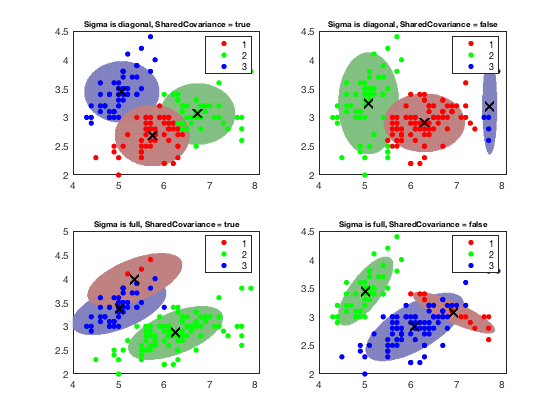

k = 3;
Sigma = {'diagonal','full'};
nSigma = numel(Sigma);
SharedCovariance = {true,false};
SCtext = {'true','false'};
nSC = numel(SharedCovariance);
d = 500;
x1 = linspace(min(X(:,1)) - 2,max(X(:,1)) + 2,d);
x2 = linspace(min(X(:,2)) - 2,max(X(:,2)) + 2,d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
threshold = sqrt(chi2inv(0.99,2));
options = statset('MaxIter',1000); % Increase number of EM iterations

figure;
c = 1;
for i = 1:nSigma;
    for j = 1:nSC;
        gmfit = fitgmdist(X,k,'CovarianceType',Sigma{i},...
            'SharedCovariance',SharedCovariance{j},'Options',options);
        clusterX = cluster(gmfit,X);
        mahalDist = mahal(gmfit,X0);
        subplot(2,2,c);
        h1 = gscatter(X(:,1),X(:,2),clusterX);
        hold on;
            for m = 1:k;
                idx = mahalDist(:,m)<=threshold;
                Color = h1(m).Color*0.75 + -0.5*(h1(m).Color - 1);
                h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
                uistack(h2,'bottom');
            end
        plot(gmfit.mu(:,1),gmfit.mu(:,2),'kx','LineWidth',2,'MarkerSize',10)
        title(sprintf('Sigma is %s, SharedCovariance = %s',...
            Sigma{i},SCtext{j}),'FontSize',8)
        legend(h1,{'1','2','3'});
        hold off
        c = c + 1;
    end
end

While the probability threshold for the confidence region determines the length of the major and minor axes, the covariance type determines the orientation of the axes.

- Diagonal covariance matrices indicate that the predictors are uncorrelated. The major and minor axes of the ellipses are parallel or perpendicular to the *x* and *y* axes. This specification increases the total number of parameters by *p*, the number of predictors, for each component, but is more parsimonious than the full covariance specification.

- Full covariance matrices allow for correlated predictors. There is no restriction to the orientation of the ellipses relative to the *x* and *y* axes. Each component increases the total number of parameters by $p(p+1)/2$, but captures correlation structure among the predictors. This specification can cause overfitting.

- Shared covariance matrices indicate that all components have the same covariance matrix. All ellipses are the same size and have the same orientation. This specification is more parsimonious than the unshared specification because the total number of parameters only increases by the number of covariance parameters for one component.

- Unshared covariance matrices indicate that all components have their own covariance matrix. The size and orientation of all ellipses might differ. This specification increases the number of parameters by *k* times the number of covariance parameters for a component, but can capture covariance differences among components.

The figure also shows that `cluster` does not always preserve cluster order. That is, if you cluster several fitted `gmdistribution` models, `cluster` might assign different cluster labels for similar components.

In most applications, the number of components, *k*, and appropriate covariance structure, $\Sigma$, are unknown. One way you can tune a GMM is by comparing information criteria. Two popular information criteria are Akaike's Information Criterion (AIC) and the Bayesian Information Criterion (BIC). Both take the optimized, negative log likelihood, and then penalize it with the number of parameters in the model (i.e., the model complexity). However, the BIC penalizes for complexity more severely than AIC. Therefore, the AIC tends to choose more complex models that might overfit, and BIC tends to choose simpler models that might underfit. A good practice is to look at both criteria when deciding on a model. Lower AIC or BIC values indicate better fitting models. You should also ensure that your choices for *k* and the covariance matrix structure is appropriate for your application. `fitgmdist` stores the AIC and BIC of fitted `gmdistribution` model objects in the properties `AIC` and `BIC`. You can access them using dot notation. For an example on choosing the appropriate parameters, see [Tune Gaussian Mixture Models](docid:stats_ug.bus8_i5-1).

## Effects of Initial Conditions

The algorithm that fits a GMM to the data can be sensitive to initial conditions. To illustrate this, consider fitting several GMMs and specify different initial conditions. Specifically, specify that, initially, most data points belong to the first cluster, two sets of random, initial assignments, and use *k*-means ++ to obtain initial cluster centers. For all instances, specify three components, unshared and full covariance matrices, the same initial mixture proportions, and the same initial covariance matrices. For stability when you try different sets of initial values, increase the number of EM algorithm iterations.

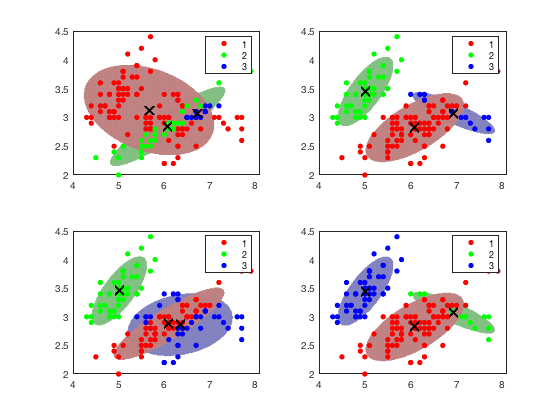

cluster0 = {[ones(n-8,1); [2; 2; 2; 2]; [3; 3; 3; 3]];...
            randsample(1:k,n,true); randsample(1:k,n,true); 'plus'};
converged = nan(4,1);
figure;
for j = 1:4;
    gmfit = fitgmdist(X,k,'CovarianceType','full',...
        'SharedCovariance',false,'Start',cluster0{j},...
        'Options',options);
    clusterX = cluster(gmfit,X);
    mahalDist = mahal(gmfit,X0);
    subplot(2,2,j);
    h1 = gscatter(X(:,1),X(:,2),clusterX);
    hold on;
    nK = numel(unique(clusterX));
    for m = 1:nK;
        idx = mahalDist(:,m)<=threshold;
        Color = h1(m).Color*0.75 + -0.5*(h1(m).Color - 1);
        h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
        uistack(h2,'bottom');
    end
	plot(gmfit.mu(:,1),gmfit.mu(:,2),'kx','LineWidth',2,'MarkerSize',10)
    legend(h1,{'1','2','3'});
    hold off
    converged(j) = gmfit.Converged;
end

sum(converged)

ans = 4

All algorithms converged. Each of the different sets of starting cluster assignments for the data points leads to a different, fitted cluster assignment. You can specify a positive integer for the name-value pair argument `'Replicates'`, which runs the algorithm the specified number of times. Subsequently, `fitgmdist` chooses the fit that yields the largest likelihood.

## When to Regularize

Sometimes, during an EM iteration, a fitted covariance matrix can become ill conditioned, that is, the likelihood is escaping to infinity. This can happen if:

- There are more predictors than data points.

- You specify to fit with too many components. 

- Variables are highly correlated. 

To overcome this problem, you can specify a small, positive number using the `'Regularize'` name-value pair argument. `fitgmdist` adds the specified small, positive number to the diagonal elements of all covariance matrices, which ensures all matrices are positive definite. Regularizing can reduce the maximal likelihood value. For more details, see [`fitgmdist`](docid:stats_ug.bt8x9gq).